Colin Keenan

ECE 5470

3-9-2020

# Homework 6

1.  High Pass Filtering

## Ideal Filter

clear

fprintf("Question 1, Ideal Filter:")

Question 1, Ideal Filter:

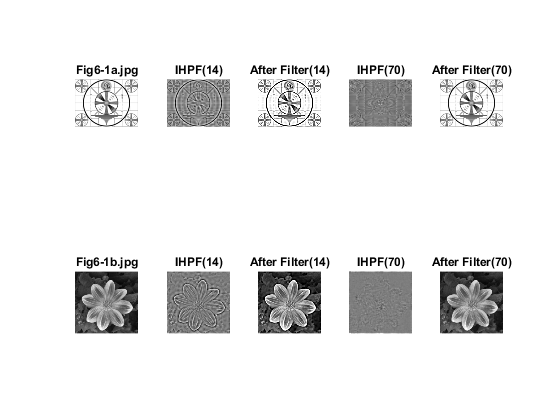


imageA = im2double(imread("Fig6-1a.jpg"));
imageB = im2double(imread("Fig6-1b.jpg"));

D0_1 =14;
D0_2 =70;

A_IHPF_1 = ihpf(imageA, D0_1);
A_IHPF_2 = ihpf(imageA, D0_2);
B_IHPF_1 = ihpf(imageB, D0_1);
B_IHPF_2 = ihpf(imageB, D0_2);

A_HP_1 = imageA + A_IHPF_1;
A_HP_2 = imageA + A_IHPF_2;
B_HP_1 = imageB + B_IHPF_1;
B_HP_2 = imageB + B_IHPF_2;

figure();
% Image A
subplot(2,5,1)
imshow(imageA);
title("Fig6-1a.jpg");
subplot(2,5,2)
imshow(A_IHPF_1, []);
title("IHPF(" + D0_1 + ")");
subplot(2,5,3)
imshow(A_HP_1);
title("After Filter(" + D0_1 + ")");
subplot(2,5,4)
imshow(A_IHPF_2, []);
title("IHPF(" + D0_2 + ")");
subplot(2,5,5)
imshow(A_HP_2);
title("After Filter(" + D0_2 + ")");

% Image B
subplot(2,5,6)
imshow(imageB);
title("Fig6-1b.jpg");
subplot(2,5,7)
imshow(B_IHPF_1, []);
title("IHPF(" + D0_1 + ")");
subplot(2,5,8)
imshow(B_HP_1);
title("After Filter(" + D0_1 + ")");
subplot(2,5,9)
imshow(B_IHPF_2, []);
title("IHPF(" + D0_2 + ")");
subplot(2,5,10)
imshow(B_HP_2);
title("After Filter(" + D0_2 + ")");

Explanation: Images were applied to an ideal high-pass filter with two different distance from 0 arguments, varying the degree and intensity of the filter. As you can see from the images, there is artifacting rings shown around the changes between the bright and dark.

## Second-Order Butterworth Filter

clear

fprintf("Question 1, Butterworth Filter:")

Question 1, Butterworth Filter:

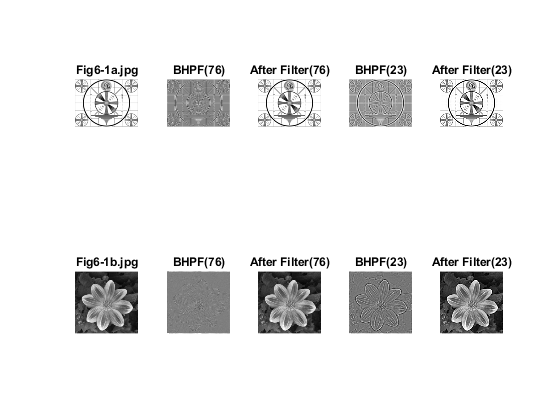


imageA = im2double(imread("Fig6-1a.jpg"));
imageB = im2double(imread("Fig6-1b.jpg"));

D0_1 =76;
D0_2 =23;

A_BHPF_1 = bhpf(imageA, D0_1);
A_BHPF_2 = bhpf(imageA, D0_2);
B_BHPF_1 = bhpf(imageB, D0_1);
B_BHPF_2 = bhpf(imageB, D0_2);

A_HP_1 = imageA + A_BHPF_1;
A_HP_2 = imageA + A_BHPF_2;
B_HP_1 = imageB + B_BHPF_1;
B_HP_2 = imageB + B_BHPF_2;

figure();
% Image A
subplot(2,5,1)
imshow(imageA);
title("Fig6-1a.jpg");
subplot(2,5,2)
imshow(A_BHPF_1, []);
title("BHPF(" + D0_1 + ")");
subplot(2,5,3)
imshow(A_HP_1);
title("After Filter(" + D0_1 + ")");
subplot(2,5,4)
imshow(A_BHPF_2, []);
title("BHPF(" + D0_2 + ")");
subplot(2,5,5)
imshow(A_HP_2);
title("After Filter(" + D0_2 + ")");

% Image B
subplot(2,5,6)
imshow(imageB);
title("Fig6-1b.jpg");
subplot(2,5,7)
imshow(B_BHPF_1, []);
title("BHPF(" + D0_1 + ")");
subplot(2,5,8)
imshow(B_HP_1);
title("After Filter(" + D0_1 + ")");
subplot(2,5,9)
imshow(B_BHPF_2, []);
title("BHPF(" + D0_2 + ")");
subplot(2,5,10)
imshow(B_HP_2);
title("After Filter(" + D0_2 + ")");

Explanation: Images were applied to a second-order butterworth high-pass filter with two different distance from 0 arguments, varying the degree and intensity of the filter. As you can see from the images, the artifacting seen in the ideal filters are gone.

## Gaussian Filter

clear

fprintf("Question 1, Gaussian Filter:")

Question 1, Gaussian Filter:

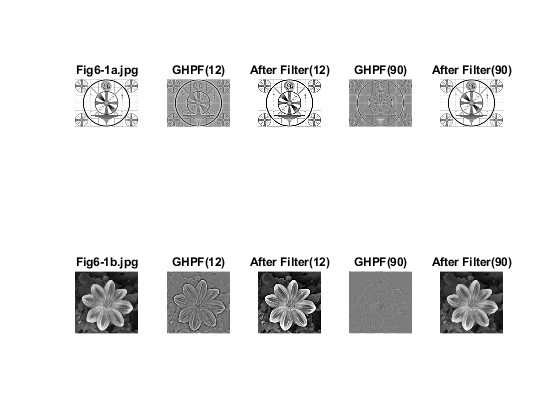


imageA = im2double(imread("Fig6-1a.jpg"));
imageB = im2double(imread("Fig6-1b.jpg"));

D0_1 =12;
D0_2 =90;

A_GHPF_1 = ghpf(imageA, D0_1);
A_GHPF_2 = ghpf(imageA, D0_2);
B_GHPF_1 = ghpf(imageB, D0_1);
B_GHPF_2 = ghpf(imageB, D0_2);

A_HP_1 = imageA + A_GHPF_1;
A_HP_2 = imageA + A_GHPF_2;
B_HP_1 = imageB + B_GHPF_1;
B_HP_2 = imageB + B_GHPF_2;

figure();
% Image A
subplot(2,5,1)
imshow(imageA);
title("Fig6-1a.jpg");
subplot(2,5,2)
imshow(A_GHPF_1, []);
title("GHPF(" + D0_1 + ")");
subplot(2,5,3)
imshow(A_HP_1);
title("After Filter(" + D0_1 + ")");
subplot(2,5,4)
imshow(A_GHPF_2, []);
title("GHPF(" + D0_2 + ")");
subplot(2,5,5)
imshow(A_HP_2);
title("After Filter(" + D0_2 + ")");

% Image B
subplot(2,5,6)
imshow(imageB);
title("Fig6-1b.jpg");
subplot(2,5,7)
imshow(B_GHPF_1, []);
title("GHPF(" + D0_1 + ")");
subplot(2,5,8)
imshow(B_HP_1);
title("After Filter(" + D0_1 + ")");
subplot(2,5,9)
imshow(B_GHPF_2, []);
title("GHPF(" + D0_2 + ")");
subplot(2,5,10)
imshow(B_HP_2);
title("After Filter(" + D0_2 + ")");

Explanation: Images were applied to a gaussian high-pass filter with two different distance from 0 arguments, varying the degree and intensity of the filter. As you can see from the images, the artifacting seen in the ideal filters are gone.

2. Bandreject Filtering

## Apply an Bandreject Filter to Fig5-2a.tif, Fig5-2b.tif. Fig6-2c.jpg

clear

fprintf("Question 2:")

Question 2:

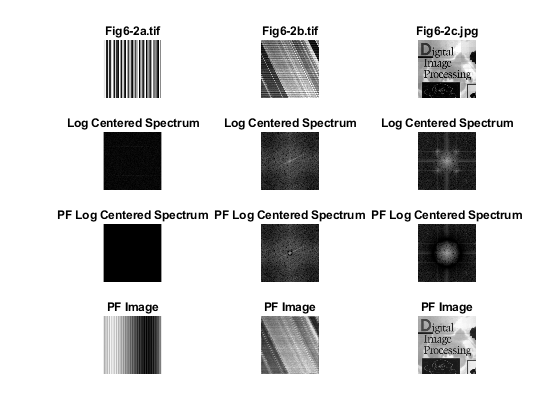


imageA = imread('Fig6-2a.tif');
imageB = imread('Fig6-2b.tif');
imageC = imread("Fig6-2c.jpg");

[AS, AcS, AeS] = cceFourierSpec(imageA);
[BS, BcS, BeS] = cceFourierSpec(imageB);
[CS, CcS, CeS] = cceFourierSpec(imageC);

A_C0 = 80;
A_W = 1000;
A_GBRF = gbrf(imageA, A_C0, A_W);
[AfS, AfcS, AfeS] = cceFourierSpec(A_GBRF);

B_C0 = 25;
B_W = 3;
B_GBRF = gbrf(imageB, B_C0, B_W);
[BfS, BfcS, BfeS] = cceFourierSpec(B_GBRF);

C_C0 = 165;
C_W = 6.9;
C_GBRF = gbrf(imageC, C_C0, C_W);
[CfS, CfcS, CfeS] = cceFourierSpec(C_GBRF);

figure();
% Original Images
subplot(4,3,1)
imshow(imageA);
title("Fig6-2a.tif");
subplot(4,3,2)
imshow(imageB);
title("Fig6-2b.tif");
subplot(4,3,3)
imshow(imageC);
title("Fig6-2c.jpg");

% Enhanced Centered Spectrums
subplot(4,3,4)
imshow(AeS, []);
title("Log Centered Spectrum");
subplot(4,3,5)
imshow(BeS, []);
title("Log Centered Spectrum");
subplot(4,3,6)
imshow(CeS, []);
title("Log Centered Spectrum");

% Post Filter Centered Spectrums
subplot(4,3,7)
imshow(AfeS, []);
title("PF Log Centered Spectrum");
subplot(4,3,8)
imshow(BfeS, []);
title("PF Log Centered Spectrum");
subplot(4,3,9)
imshow(CfeS, []);
title("PF Log Centered Spectrum");

% Post Filter Images
subplot(4,3,10)
imshow(A_GBRF, []);
title("PF Image")
subplot(4,3,11)
imshow(B_GBRF, []);
title("PF Image")
subplot(4,3,12)
imshow(C_GBRF, []);
title("PF Image")

Explanation: Each of the images were applied with a Gaussian Band Reject filter with unique parameterrs adjusted per image to eliminated various errors. In the first image, the underlying gradiant was revealed by eliminating all unecessary frequencies. In the second image, the horizontal lines were eliminated by a similar band reject filter, but in this case the horizontal lines are close to the center of the frequency spectrum. In the third image, the cross hatch pattern was eliminated by eliminating the 4 loci located around the center area on the spectrum.

3.  Filtering

## Filter and Threshold Fig6-3.tif to optimize image clarity

clear

fprintf("Question 3:")

Question 3:

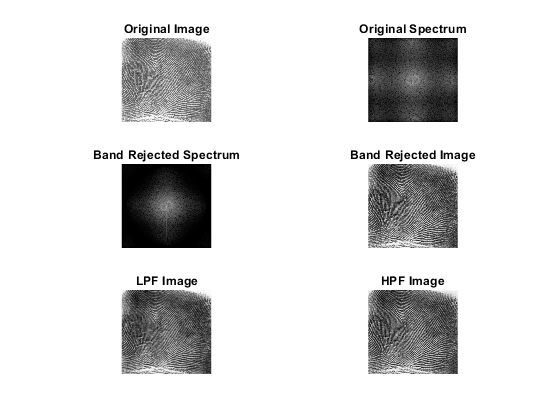


image = im2double(imread('Fig6-3.tif'));

[S, cS, eS] = cceFourierSpec(image);

C0 = 481;
W = 25.3;
GBRF = gbrf(image, C0, W);
[FS, FcS, FeS] = cceFourierSpec(GBRF);

D0_L = 61;
LP = glpf(GBRF, D0_L);

D0_H = 40;
HPF = ghpf(LP, D0_H);
HP = LP + HPF;

figure();
subplot(3,2,1)
imshow(image);
title("Original Image");
subplot(3,2,2)
imshow(eS, []);
title("Original Spectrum");
subplot(3,2,3)
imshow(FeS, []);
title("Band Rejected Spectrum");
subplot(3,2,4)
imshow(GBRF, []);
title("Band Rejected Image");
subplot(3,2,5)
imshow(LP, []);
title("LPF Image");
subplot(3,2,6)
imshow(HP, []);
title("HPF Image");

Explanation: Multiple filters were applied to this fingerprint image in an attempt to improve the clarity of the pattern. First a band reject filter was applied to eliminate uneccessary and noisy high frequencies. Then a low pass filter was applied to join potentially disjoint lines. Then a high pass filter was applied to the low pass filtered image to show the edges more.

## Appendix (Functions Used)

function filtered = ihpf(imag, D0)
% Description: Perform an Ideal High-Pass Filter to an image with the given sigma

% Initial Variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Ideal Filter
H = double(D>D0);

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end


function filtered = bhpf(imag, D0)
% Description: Perform an Butterworth High-Pass Filter to an image with the given sigma

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Butterworth Filter: default n value
n=2;
H=1./(1+(D0./D).^(2*n));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end


function filtered = ghpf(imag, D0)
% Description: Perform an Gaussian High-Pass Filter to an image with the given sigma

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Gaussian Filter
H = 1-exp(-(D.^2)./(2*(D0^2)));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end

function filtered = gbrf(imag, C0, W)
% Description: Perform an Gaussian Band Reject Filter to an image with the given
% Center and Width of the band

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Gaussian Filter
H = 1-exp(-(((D-C0).^2)./(D.*W^2)));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end

function [S,cS,eS] = cceFourierSpec(imag)
% Description: Compute, Center, and Enhance a Fourier Spectrum of an Image

% Base FFT
F = fft2(im2double(imag));

% Spectrum
S = abs(F);

% Centered Spectrum
cF = fftshift(F);
cS = abs(cF);

% Enhanced Spectrum
eS = log(1+abs(cF));
end

function filtered = blpf(imag, D0)
% Description: Perform an Butterworth Low-Pass Filter to an image with the given sigma

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Butterworth Filter: default n value
n=2;
H=1./(1+(D./D0).^(2*n));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end

function filtered = glpf(imag, D0)
% Description: Perform an Gaussian Low-Pass Filter to an image with the given sigma

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Gaussian Filter
H = exp(-(D.^2)./(2*(D0^2)));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end